clear all
clc
close all

A = [-1.417 1 ; 2.86 -1.183];
B = [0 ; -3.157];

Values of Q and R

R = 5; % final gain = 1/R
Q = [0 0 ; 0 1];  % because q^2 = x'Qx

Value of N

N = [1 0];  % Q = N'*N

Controllability and Observability

rank(ctrb(A,B)) % Fully controllable

ans = 2

rank(obsv(A,N)) % Fully observable

ans = 2

Solving the Algebraic Ricatti Equation

% Hamiltonian Matrix
H = [A -B*inv(R)*B' ; -Q -A']

H = 1.0e+04 *

   -0.0001    0.0001         0         0
    0.0003   -0.0001         0   -1.4850
         0         0    0.0001   -0.0003
         0   -0.0001   -0.0001    0.0001



% Symmetry of H
eig(H)

ans =  -121.8910
  121.8910
   -1.4167
    1.4167



[V,D] = eig(H)

V =    -0.0083   -0.0081   -1.0000   -0.2421
    0.9999   -0.9999   -0.0003   -0.6861
    0.0002   -0.0002   -0.0002    0.6861
    0.0081    0.0083   -0.0002    0.0001


D =  -121.8910         0         0         0
         0  121.8910         0         0
         0         0   -1.4167         0
         0         0         0    1.4167



% eigenvectors corresponding to negative eigenvalues
X = V(:,1:2)

X =    -0.0083   -0.0081
    0.9999   -0.9999
    0.0002   -0.0002
    0.0081    0.0083


X1 = X(1:2,:);
X2 = X(3:4,:);

P = X2*inv(X1)

P =     0.0005    0.0002
   -1.0002   -0.0002



% Checking that P=P'>=0
eig(P)

ans =    0.0002 + 0.0139i
   0.0002 - 0.0139i



% Control K
K = inv(R)*B'*P

K = 1.0e+03 *

    4.7046    0.0008


eig(A-B*K)

ans =  -121.8910
  121.8910



% Function to do it all
[Pc,Kc,CL_eig] = icare(A,B,Q,R)

Pc =     0.0002    0.0002
    0.0002    0.0081


Kc =    -0.8942  -38.2350


CL_eig =    -1.4167
 -121.8910


Check the Robustness Property of LQR

% L = K*phi(s)*B = K*(sI-A)^(-1)*B

[numL,denL] = ss2tf(A,B,K,0)

numL = 1.0e+04 *

         0   -0.0003   -1.4856


denL =     1.0000    2.6000   -1.1837


L = tf(numL,denL)

L =
 
   -2.6 s - 1.486e04
  -------------------
  s^2 + 2.6 s - 1.184
 
Continuous-time transfer function.



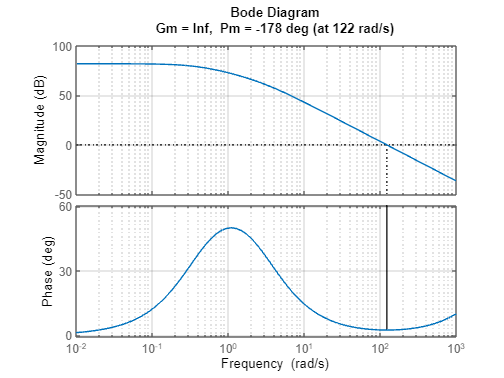

margin(L)
grid on

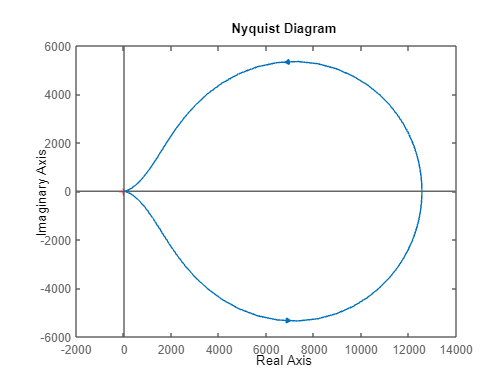

nyquist(L) % always outside the circle centered at -1

Chang-Letov Design

% F = N*phi(s)*B : Fictitious transfer function

[numF,denF] = ss2tf(A,B,N,0);
F = tf(numF,denF)

F =
 
        -3.157
  -------------------
  s^2 + 2.6 s - 1.184
 
Continuous-time transfer function.



% In order to get F(-s), we replace A with (-A)
% F(s) = N(sI-A)^(-1)*B
% F(-s) = -N*(sI-(-A))^(-1)*B

[numFms,denFms] = ss2tf(-A,B,-N,0);
Fms = tf(numFms,denFms)

Fms =
 
        -3.157
  -------------------
  s^2 - 2.6 s - 1.184
 
Continuous-time transfer function.



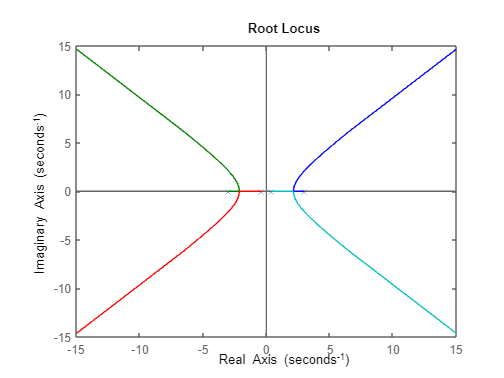

% Symmetric root locus

rlocus(F*Fms)